% The row names are different exposures
rowNames = {'1/4', '1/5', '1/6', '1/8', '1/10', '1/13', '1/15', '1/20', '1/25', '1/30', '1/40', '1/50', '1/60', '1/80', '1/100'};
% The column names are concentrations
colNames = {'0', '0.2', '0.5', '1', '2', '5', '10', '20', '50'};
% Sepcify the variable types
varTypes = {'double', 'double', 'double', 'double', 'double', 'double', 'double', 'double', 'double'};
% Create tables for the data
MeanIntens = table('Size', [15, 9], 'VariableTypes', varTypes, 'VariableNames', colNames, 'RowNames', rowNames);
MaxIntens = table('Size', [15, 9], 'VariableTypes', varTypes, 'VariableNames', colNames, 'RowNames', rowNames);
MinIntens = table('Size', [15, 9], 'VariableTypes', varTypes, 'VariableNames', colNames, 'RowNames', rowNames);
StdIntens = table('Size', [15, 9], 'VariableTypes', varTypes, 'VariableNames', colNames, 'RowNames', rowNames);
intesBackground = cell(length(rowNames),1);

% Select folder for images
[calImgFold] = uigetdir('../','Select the folder of calibration images');
fprintf('------------------\nReading images from %s\n------------------\n',...
    calImgFold);

------------------
Reading images from C:\Users\oshri\Documents\Projects\Unsaturated heterogeneity\Experimental images\Calibration_02-07-20
------------------


% Folders
folds = dir(fullfile(calImgFold, 'C=*'));

% Find the image for C = 0, to subtract from the others
for t = 1:length(folds)
if cell2mat(regexp(folds(t).name, '(?<=C=)\d*.\d|\d*', "match"))=='0'

% get the image name
fmt = '.tif';
imgList = dir(fullfile(calImgFold, folds(t).name, ['*' fmt]));
imgListCell = struct2cell(imgList);
imgNames = {imgListCell{1,:}};

% Load the images and save the quantitative data
for n = 1:length(imgNames)
intesBackground{n} = imread(fullfile(calImgFold, folds(t).name, imgNames{n}));
end

end
end

% Calculate for all images
for t = 1:length(folds)
if any(cell2mat(regexp(folds(t).name, '(?<=C=)\d*.\d|\d*', "match"))~='0')

% Find the concentration
CName = regexp(folds(t).name, '(?<=C=)\d*.\d|\d*', "match");
    
% Find the images in the folder
fmt = '.tif';
imgList = dir(fullfile(calImgFold, folds(t).name, ['*' fmt]));
imgListCell = struct2cell(imgList);
imgNames = {imgListCell{1,:}};

% Load the images and save the quantitative data
for n = 1:length(imgNames)
% Read the image
imageRaw = imread(fullfile(calImgFold, folds(t).name, imgNames{n}));
% % Subtract the background [not possible due to different sizes of images]
% imageBackSubstract = imageRaw - cell2mat(intesBackground(n));
% Save the average intensity
MeanIntens(n,CName) = {mean(imageRaw, "all")};
% MeanIntens(n,CName) = {mean(imageRaw, "all") - mean(cell2mat(intesBackground(n)), "all")};
% % Save the maximum intensity
% MaxIntens(n,CName) = {max(imageBackSubstract(:))};
% % Save the minimum intensity
% MinIntens(n,CName) = {min(imageBackSubstract(:))};
% % Save the standard deviation of intensity
% StdIntens(n,CName) = {std(double(imageBackSubstract(:)))};
end
end
end

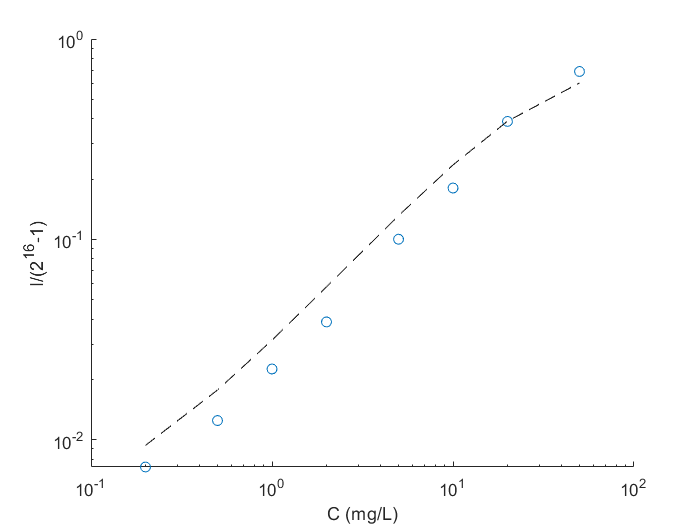

MeanIntensVars = MeanIntens.Variables;

% Choose the exposure to plot/fit
expToPlot = 7; % 5: 1/10

figure(1)
clf
ax = gca;
hold on
plot([0.2, 0.5, 1, 2, 5, 10, 20, 50], MeanIntensVars(expToPlot, 2:end)/(2^(16)-1), 'o')
% The maximum intensity
I0 = max(MeanIntensVars(expToPlot, 2:end)/(2^(16)-1));
% The background intensity
Ib = mean(cell2mat(intesBackground(expToPlot)), "all")/(2^(16)-1);
% Fit the intensity model
modIntens = @(b,x) I0.*(1-exp(-b.*x))+Ib;
p0 = 0.1;
xfit = [0.2, 0.5, 1, 2, 5, 10, 20, 50];
yfit = MeanIntensVars(expToPlot, 2:end)/(2^(16)-1);
mdl = fitnlm(xfit,yfit,modIntens,p0);
% Plot the fitted model
plot(xfit, modIntens(mdl.Coefficients.Estimate,xfit), 'k--')
ax.XLabel.String = 'C (mg/L)';
ax.YLabel.String = 'I/(2^{16}-1)';
ax.XScale = "log";
ax.YScale = "log";